## **Flight Path Visualizations with Simulated Flight Data**

## **Rubén Armando Figueroa Fuentes**

Project within the Aerospace Coding Projects of my Portfolio

Since we may have privacy concerns about flight data of different companies and industries, we will simulate this coordinates first with our Matlab Program using mathematical equations. We will use the standard latitude and longitude data from Hermosillo, Sonora, México, my local city. With these data, we will be able to simulate a flight path.

points= 200; %measurement
ini_latitude= 29.1026;
ini_longitude= -110.97732;
ini_altitude= 656.168; %in feet
speed=499.66134; %average speed of commercial plane
%This data was found of 575 mph, but converted to knots
%for nautical navigation preference

%Simulated flight path
latitude= ini_latitude+ randn(points,1)*0.02;
%We include random to simulate standard deviation
%and multiply by 0.02 for this to not affect the complete
%flight path, just standards deviation
longitude=ini_longitude+rand(points,1)*0.02;
time=(1:points)*10;%Time simulation of flight with an
%increment of 10 seconds, from first to last data point

%Upload our data to a csv file
flight_path_Data=[time',latitude, longitude, ini_altitude* ones(points,1),speed* ones(points,1)]; %altitude and speed
%all ones since they remain constant
csvwrite('C:\Users\Ruben\OneDrive\Escritorio\Matlab\Aerospace_coding_projects\flight_path_Data.csv', flight_path_Data);  %func
%This will work for my specific directory

Now, we can plot this information

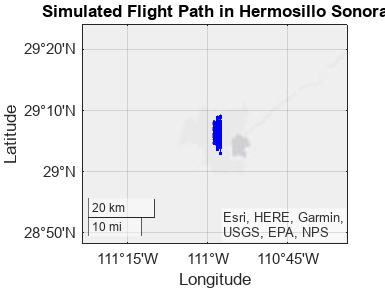

%Data from csv_file
flight_path_Data=csvread('flight_path_Data.csv');

%Plot flight path
figure;
%geoplot syntax geoplot(latitude, longitude, color)
geoplot(flight_path_Data(:,2),flight_path_Data(:,3),'b.-'); %Retrieves only second and third column
%which are latitude and longitude
geolimits([ini_latitude-0.3,ini_latitude+0.3],[ini_longitude-0.3,ini_longitude+0.3]); %Range of limits for zoom
title('Simulated Flight Path in Hermosillo Sonora');

We can also make these model as a 3D path like the following, changing to three dimension by adjusting the altitude: 

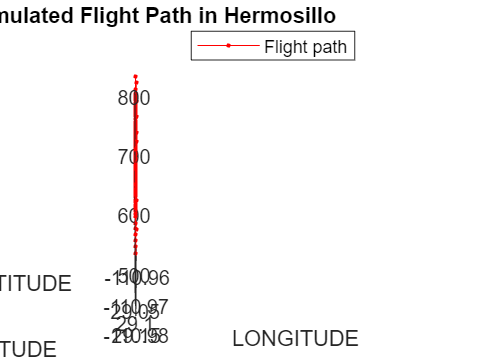

points= 200; %measurement
ini_latitude= 29.1026;
ini_longitude= -110.97732;
ini_altitude= 656.168; %in feet
speed=499.66134; %average speed of commercial plane
%This data was found of 575 mph, but converted to knots
%for nautical navigation preference

%Simulated flight path
latitude= ini_latitude+ randn(points,1)*0.02;
%We include random to simulate standard deviation
%and multiply by 0.02 for this to not affect the complete
%flight path, just standards deviation
longitude=ini_longitude+rand(points,1)*0.02;
altitude= ini_altitude+ randn(points,1)*50; %Processed 3D Deviation
time=(1:points)*10;%Time simulation of flight with an
%increment of 10 seconds, from first to last data point

%Upload our data to a csv file
flight_path_3D_Data=[time',latitude, longitude, altitude,speed* ones(points,1)]; %altitude and speed %now altitude will be different
%all ones since they remain constant
csvwrite('C:\Users\Ruben\OneDrive\Escritorio\Matlab\Aerospace_coding_projects\flight_path_3D_Data.csv', flight_path_3D_Data);  %func
%This will work for my specific directory %This file needs to be closed in
%excel in order to use it here

%3D config
figure;
plot3(flight_path_3D_Data(:,2),flight_path_3D_Data(:,3),flight_path_3D_Data(:,4),'r.-');
%Labels
xlabel('LATITUDE');
ylabel('LONGITUDE');
zlabel('ALTITUDE');
view(20,20);
title('3D Simulated Flight Path in Hermosillo');
legend('Flight path');


%Is it messy because of the noise in altitude?

We will include a color mapping technique to represent the changes in altitude regarding our new simulated coordinates of Hermosillo Sonora

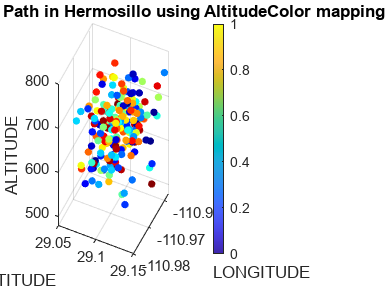

figure;
altitude_colormap= jet(points); %function for color mapping
scatter3(latitude,longitude,altitude,20,altitude_colormap,"filled")
xlabel('LATITUDE');
ylabel('LONGITUDE');
zlabel('ALTITUDE');
view(25,25);
title('3D Simulated Flight Path in Hermosillo using AltitudeColor mapping');
colorbar;

The colorbar represents the difference in altitude values in our simulation. Ranging from blue (low altitude values) to red (highest altitude values).

References 

*Coordenadas geográficas de Hermosillo, SON, México*. (s. f.). Geodatos. https://www.geodatos.net/coordenadas/mexico/hermosillo